# **Observer Trajectory Generation**

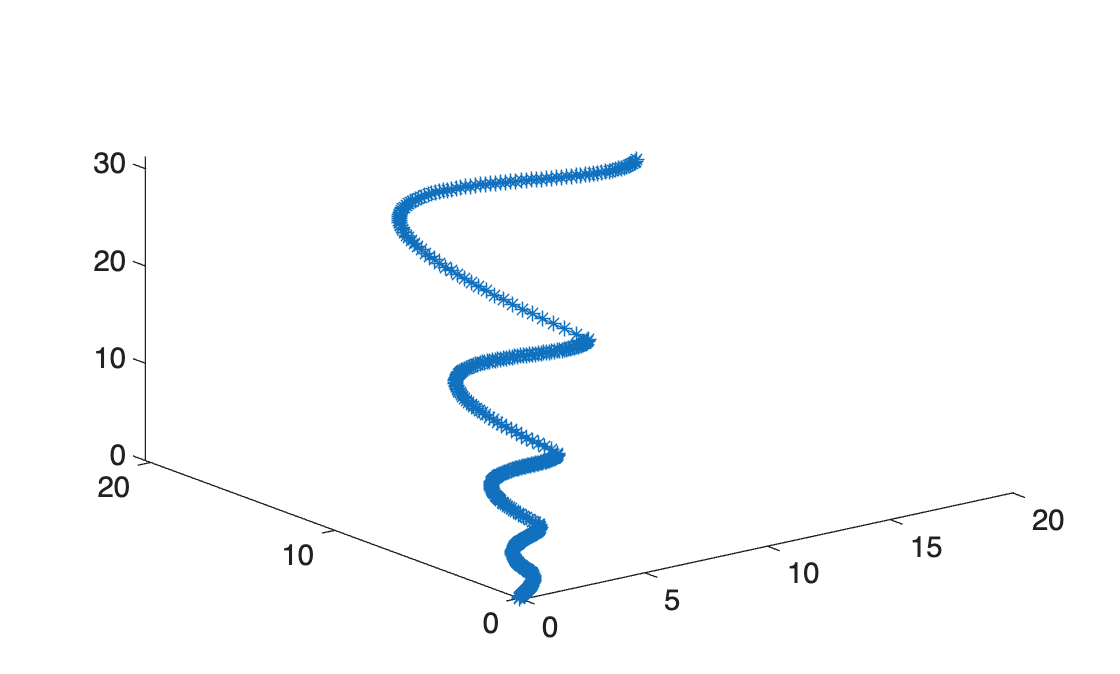

clc; clear;
addpath('/Users/hongseokkim/Desktop/Redstone_DP_RPOD/');
load('glideslope_LVLH.mat')
% load('two_impulse_LVLH.mat')
% load('circumnav_LVLH.mat')
chaser_r_LVLH = delta_r_t_mat;
target_r_LVLH = zeros(length(time_vector),3);



number_of_timesteps = 10;

selected_index = floor(1:length(time_vector)/number_of_timesteps:length(time_vector));

r_chaser = chaser_r_LVLH(selected_index,:);
r_target = target_r_LVLH(selected_index,:);
t_vector = time_vector(selected_index);

plot3(chaser_r_LVLH(:,1),chaser_r_LVLH(:,2),chaser_r_LVLH(:,3),'*-')

% Example input

MDP = generate_lattice_states(r_chaser, r_target, t_vector);

MDP = initialize_MDP_value_space(MDP,n);

t_idx =      9


t_idx =      8


t_idx =      7


t_idx =      6


t_idx =      5


t_idx =      4


t_idx =      3


t_idx =      2


t_idx =      1



% start_state_idx = 26;
% next_state_idx = 8;


start_state_idx = MDP.time_index_1.optimal_starting_state;
next_state_idx = MDP.time_index_1.(['current_state_index_', num2str(start_state_idx)]).optimal_next_state;

traj = extract_optimal_observer_trajectory(MDP, start_state_idx, next_state_idx)

traj = 다음 필드를 포함한 1×9 struct 배열:
    time_index
    time
    previous_state_index
    current_state_index
    optimal_next_state_index
    current_state
    next_state
    departure_velocity
    delta_t
    state_value


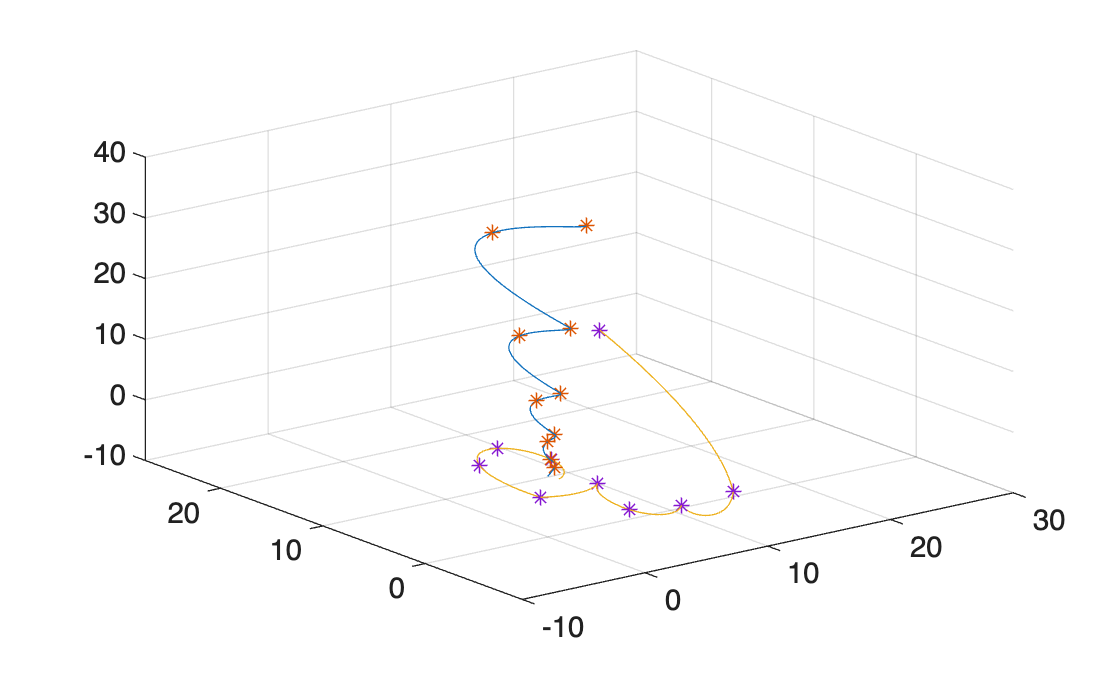


observer_position = reshape([traj.current_state], 3, [])';
observer_velocity = reshape([traj.departure_velocity], 3, [])';
delta_t_vector = vertcat(traj.delta_t);
state_value_vector = vertcat(traj.state_value);
optimal_next_index_vector = vertcat(traj.optimal_next_state_index);




r_observer = [];

for index = 1:length(observer_position(:,1))
[r_mat, ~] = drow_trajctory(observer_position(index,:)', observer_velocity(index,:)', delta_t_vector(index), n);
r_observer = [r_observer;r_mat];
end

figure;
hold on
plot3(chaser_r_LVLH(:,1),chaser_r_LVLH(:,2),chaser_r_LVLH(:,3))
scatter3(r_chaser(:,1),r_chaser(:,2),r_chaser(:,3),'*')
plot3(r_observer(:,1),r_observer(:,2),r_observer(:,3))
scatter3(observer_position(:,1),observer_position(:,2),observer_position(:,3),'*')
view(3)
hold off
grid on

function MDP = generate_lattice_states(r_chaser, r_target, t_vector)
%--------------------------------------------------------------------------
% generate_lattice_states
%
% Handwritten-page-based MATLAB implementation
%
% INPUTS
%   r_chaser : [N x 3] chaser positions in LVLH
%   r_target : [N x 3] target positions in LVLH
%   t_vector : [N x 1] or [1 x N] time vector
%
% OUTPUT
%   state_data : structure array with fields
%       .time_idx
%       .time
%       .point_idx
%       .xyz
%
% NOTES
%   - theta_fov_min = 40 deg
%   - theta_fov_max = 80 deg
%   - 13 lattice points are generated on Circle 2 plane
%   - Remaining points are rotated 7 times by +45 deg about axis CT
%--------------------------------------------------------------------------

    %% ---------------- User parameters ----------------
    theta_fov_min_deg = 40;
    theta_fov_max_deg = 80;
    n_rotations       = 7;      % "Do this 7 time"
    rotation_step_deg = 45;     % +45 deg
    make_plot         = false;   % set false if plotting is not needed

    %% Basic checks
    if size(r_chaser,2) ~= 3 || size(r_target,2) ~= 3
        error('r_chaser and r_target must be N x 3 arrays.');
    end
    if size(r_chaser,1) ~= size(r_target,1)
        error('r_chaser and r_target must have the same number of rows.');
    end

    N = size(r_chaser,1);
    t_vector = t_vector(:);
    if length(t_vector) ~= N
        error('Length of t_vector must match number of rows of r_chaser/r_target.');
    end

    %% Convert angles
    theta_min = deg2rad(theta_fov_min_deg);
    theta_max = deg2rad(theta_fov_max_deg);

    %% Output container
    MDP = struct();


    %% ================= Main loop over time =================
    for k = 1:N
        %------------------------------------------------------
        % Step (i): C, T
        %------------------------------------------------------
        C = r_chaser(k,:).';
        T = r_target(k,:).';

        CT = T - C;
        L_CT = norm(CT);

        if L_CT < 1e-12
            warning('Time index %d skipped because C and T are identical.', k);
            continue;
        end

        u_CT = CT / L_CT;

        %------------------------------------------------------
        % Step (ii): M, E, F
        %------------------------------------------------------
        M = 0.5*(C + T);
        E = 0.5*(C + M);
        F = 0.5*(M + T);

        CM = M - C;
        L_CM = norm(CM);

        %------------------------------------------------------
        % Step (iii), (iv):
        % Need a perpendicular direction to CT (or CM)
        % Choose a robust perpendicular vector using cross product
        %------------------------------------------------------
        n1 = choose_perpendicular_unit_vector(u_CT);  % in plane normal to CT
        n2 = u_CT / norm(u_CT);

        % Interpreted from note:
        % |MA| = |CM| * tan(theta_min/2)
        % |MB| = |CM| * tan(theta_max/2)
        %
        % A and B lie in the plane normal to CT and passing through M.
        dA = L_CM * tan(theta_min/2);
        dB = L_CM * tan(theta_max/2);

        A = M + dA * n1;
        B = M + dB * n1;

        %------------------------------------------------------
        % Step (V): Circle 1 and Circle 2
        % radius AC = AT, BC = BT by construction
        %------------------------------------------------------
        r1 = norm(A - C);   % same as norm(A - T)
        r2 = norm(B - C);   % same as norm(B - T)

        %------------------------------------------------------
        % Step (VI): Generate 13 lattice dots in Circle 2
        %
        % We create 2D integer lattice:
        %   (i,j) with i^2 + j^2 <= 4
        % This gives exactly 13 points:
        %   radius = 2 in lattice units
        %
        % Then scale by (r2/2) so outer ring lies on Circle 2.
        %------------------------------------------------------
        lattice_pts = [];
        spacing = r2 / 2;

        idx_local = 1;
        for i = -2:2
            for j = -2:2
                if i^2 + j^2 <= 4
                    p = B + spacing*i*n1 + spacing*j*n2;
                    lattice_pts(:,idx_local) = p;
                    idx_local = idx_local + 1;
                end
            end
        end
        % lattice_pts is 3 x 13

        %------------------------------------------------------
        % Delete lattice dots if:
        % 1) distance(point, M) < |AM|
        % 2) distance(point, C) < |CE|
        % 3) distance(point, T) < |FT|
        %------------------------------------------------------
        th1 = norm(A - C);
        th2 = norm(C - E);
        th3 = norm(F - T);

        keep_mask = true(1, size(lattice_pts,2));

        for pidx = 1:size(lattice_pts,2)
            P = lattice_pts(:,pidx);

            cond1 = norm(P - M) < th1;
            cond2 = norm(P - C) < th2;
            cond3 = norm(P - T) < th3;

            if cond1 || cond2 || cond3
                keep_mask(pidx) = false;
            end
        end

        lattice_pts_kept = lattice_pts(:, keep_mask);

        %------------------------------------------------------
        % Step (VII):
        % Rotate remaining lattice points by +45 deg about axis CT
        % Do this 7 times
        % Save all drawn lattice point locations
        %------------------------------------------------------
        all_pts_this_time = lattice_pts_kept;
        current_pts = lattice_pts_kept;

        for rr = 1:n_rotations
            angle_rad = deg2rad(rotation_step_deg * rr);

            rotated_pts = zeros(size(current_pts));
            for pidx = 1:size(current_pts,2)
                rotated_pts(:,pidx) = rotate_point_about_axis( ...
                    current_pts(:,pidx), C, u_CT, angle_rad);
            end

            all_pts_this_time = [all_pts_this_time, rotated_pts]; %#ok<AGROW>
        end

        %------------------------------------------------------
        % Save results
        % Save: State, timestep, point index_j = (x,y,z)
        %------------------------------------------------------
        % for pidx = 1:size(all_pts_this_time,2)
        %     state_data(save_counter).time_idx  = k;
        %     state_data(save_counter).time      = t_vector(k);
        %     state_data(save_counter).point_idx = pidx;
        %     state_data(save_counter).xyz       = all_pts_this_time(:,pidx).';
        %     save_counter = save_counter + 1;
        % end
        MDP.(['time_index_',num2str(k)]).time_info = t_vector(k);
        for point_index = 1:size(all_pts_this_time,2)
        MDP.(['time_index_',num2str(k)]).(['current_state_index_',num2str(point_index)]).state_info = all_pts_this_time(:,point_index);
        end
        %------------------------------------------------------
        % Optional plot
        %------------------------------------------------------
        if make_plot
            figure(100); clf; hold on; grid on; axis equal;
            title(sprintf('Time index = %d, t = %.3f', k, t_vector(k)));
            xlabel('x'); ylabel('y'); zlabel('z');

            % Plot C, T, M, A, B
            plot3(C(1), C(2), C(3), 'bo', 'MarkerFaceColor','b', 'DisplayName','C');
            plot3(T(1), T(2), T(3), 'ro', 'MarkerFaceColor','r', 'DisplayName','T');
            plot3(M(1), M(2), M(3), 'ko', 'MarkerFaceColor','k', 'DisplayName','M');
            plot3(A(1), A(2), A(3), 'go', 'MarkerFaceColor','g', 'DisplayName','A');
            plot3(B(1), B(2), B(3), 'mo', 'MarkerFaceColor','m', 'DisplayName','B');

            % Plot CT line segment
            plot3([C(1) T(1)], [C(2) T(2)], [C(3) T(3)], 'k-', 'LineWidth', 1.5, ...
                'DisplayName','CT');

            % Plot circles
            plot_circle3D(A, u_CT, r1, n1, n2, 'g-');
            plot_circle3D(B, u_CT, r2, n1, n2, 'm-');

            % Plot kept lattice before rotation
            if ~isempty(lattice_pts_kept)
                scatter3(lattice_pts_kept(1,:), lattice_pts_kept(2,:), lattice_pts_kept(3,:), ...
                    50, 'filled', 'MarkerFaceColor', [1 0 0], 'DisplayName','Kept lattice');
            end

            % Plot all rotated points
            if ~isempty(all_pts_this_time)
                scatter3(all_pts_this_time(1,:), all_pts_this_time(2,:), all_pts_this_time(3,:), ...
                    20, 'filled', 'MarkerFaceColor', [0.85 0.33 0.1], ...
                    'DisplayName','All rotated states');
            end

            legend('Location','bestoutside');
            view(3)
            drawnow;
        end
    end
end

%% ========================================================================
function n = choose_perpendicular_unit_vector(u)
% Return a unit vector perpendicular to u

    ex = [1;0;0];
    ey = [0;1;0];
    ez = [0;0;1];

    c1 = cross(u, ex);
    c2 = cross(u, ey);
    c3 = cross(u, ez);

    norms = [norm(c1), norm(c2), norm(c3)];
    [~, idx] = max(norms);

    switch idx
        case 1
            n = c1 / norm(c1);
        case 2
            n = c2 / norm(c2);
        case 3
            n = c3 / norm(c3);
    end
end

%% ========================================================================
function p_rot = rotate_point_about_axis(p, axis_point, axis_dir, angle_rad)
% Rodrigues rotation formula around arbitrary axis
%
% p          : 3x1 point
% axis_point : 3x1 point on axis
% axis_dir   : 3x1 unit vector
% angle_rad  : scalar

    v = p - axis_point;
    k = axis_dir / norm(axis_dir);

    v_rot = v*cos(angle_rad) + ...
            cross(k, v)*sin(angle_rad) + ...
            k*(dot(k, v))*(1 - cos(angle_rad));

    p_rot = axis_point + v_rot;
end

%% ========================================================================
function plot_circle3D(center, normal_vec, radius, e1, e2, styleStr)
% Plot a circle in 3D with given plane basis e1,e2

    th = linspace(0, 2*pi, 200);
    circle_pts = center + radius*(e1*cos(th) + e2*sin(th));
    plot3(circle_pts(1,:), circle_pts(2,:), circle_pts(3,:), styleStr, 'LineWidth',1.2);
end

function MDP = initialize_MDP_value_space(MDP, n)
%--------------------------------------------------------------------------
% initialize_MDP_value_space
%
% Add value/reward/action/velocity fields to an already generated MDP struct.
%
%--------------------------------------------------------------------------

    time_fields = fieldnames(MDP);
    num_time = length(time_fields);




    % ==========================================================
    % Final timestep: terminal state value = 0
    % ==========================================================
    final_time_field = time_fields{num_time};
    current_state_fields = fieldnames(MDP.(final_time_field));
    idx = startsWith(current_state_fields, 'current_state_index_');
    current_state_fields = current_state_fields(idx);


    previous_time_index = time_fields{num_time-1};
    previous_state_fields = fieldnames(MDP.(previous_time_index));
    idx = startsWith(previous_state_fields, 'current_state_index_');
    previous_state_fields = previous_state_fields(idx);
    num_previous_states = length(previous_state_fields);
                

    

    for i = 1:length(current_state_fields)
        current_state_index = current_state_fields{i};
        for p_idx = 1:num_previous_states
        % At final timestep, value is zero.
        % We store it as scalar because no future action remains.
        MDP.(final_time_field).(current_state_index).(['previous_state_index_', num2str(p_idx)]).state_value = 0;
        end
    end

    % ==========================================================
    % Backward initialization: t = T-1, ..., 1
    % ==========================================================
    for t_idx = num_time-1:-1:1
        t_idx
        time_index = time_fields{t_idx};
        next_time_index    = time_fields{t_idx+1};

        current_state_fields = fieldnames(MDP.(time_index));
        idx = startsWith(current_state_fields, 'current_state_index_');
        current_state_fields = current_state_fields(idx);


        next_state_fields    = fieldnames(MDP.(next_time_index));
        idx = startsWith(next_state_fields, 'current_state_index_');
        next_state_fields = next_state_fields(idx);

        num_current_states = length(current_state_fields);
        num_next_states    = length(next_state_fields);


        t_current = MDP.(time_index).time_info;
        t_next = MDP.(next_time_index).time_info;
        optimal_starting_state_candidates = [];

        for i = 1:num_current_states

            current_state_index = current_state_fields{i};

            r_current = MDP.(time_index).(current_state_index).state_info;

            % --------------------------------------------------
            % previous_state_index dimension
            %
            % At t = 1, there may be no previous state.
            % Here we use one dummy previous index.
            % For t > 1, previous states are states at t-1.
            % --------------------------------------------------
            if t_idx == 1
                num_previous_states = 1;
            else
                previous_time_index = time_fields{t_idx-1};
                previous_state_fields = fieldnames(MDP.(previous_time_index));
                idx = startsWith(previous_state_fields, 'current_state_index_');
                previous_state_fields = previous_state_fields(idx);
                num_previous_states = length(previous_state_fields);
                t_previous = MDP.(previous_time_index).time_info;
            end


            for n_idx = 1:num_next_states

                next_state_index = ['next_state_index_', num2str(n_idx)];

                % --------------------------------------------------
                % 1. Departure velocity
                %    v_depart(s_k, s_{k+1})
                % --------------------------------------------------


                delta_t_next_current = t_next - t_current;
                r_next = MDP.(next_time_index).(['current_state_index_',num2str(n_idx)]).state_info;

                [v1, ~] = get_v1_and_v2(r_current, r_next, delta_t_next_current, n);
                MDP.(time_index).(current_state_index).(next_state_index).departure_velocity = v1;

                if t_idx == 1
                   MDP.(time_index).(current_state_index).(next_state_index).delta_t = delta_t_next_current; 
                end

            end

            if t_idx > 1
            for p_idx = 1:num_previous_states

                previous_state_index = ['previous_state_index_', num2str(p_idx)];
                % --------------------------------------------------
                % 2. Arrival velocity
                %    v_arrive(s_{k-1}, s_k)
                % --------------------------------------------------

                delta_t_current_prev = t_current - t_previous;
                r_previous = MDP.(previous_time_index).(['current_state_index_',num2str(p_idx)]).state_info;
                [~, v2] = get_v1_and_v2(r_previous, r_current, delta_t_current_prev, n);
                MDP.(time_index).(current_state_index).(previous_state_index).arrival_velocity = v2;


                state_value_candidates = [];
                for n_idx = 1:num_next_states
                    next_state_index = ['next_state_index_', num2str(n_idx)];
                % --------------------------------------------------
                % 3,4: Reward info and action value
                %    R(s_{k-1}, s_k, s_{k+1})
                %    Q(s_{k-1}, s_k, s_{k+1})
                % --------------------------------------------------
                    arrival_velocity = MDP.(time_index).(current_state_index).(previous_state_index).arrival_velocity;
                    departure_velocity = MDP.(time_index).(current_state_index).(next_state_index).departure_velocity;
                    reward = - norm(departure_velocity - arrival_velocity);

                    MDP.(time_index).(current_state_index).(previous_state_index).(next_state_index).reward = reward;
                    
                    next_state_value = MDP.(next_time_index).(['current_state_index_',num2str(n_idx)]).(['previous_state_index_',num2str(i)]).state_value;

                    action_value = reward + next_state_value;

                    MDP.(time_index).(current_state_index).(previous_state_index).(next_state_index).action_value = action_value;

                    state_value_candidates = [state_value_candidates, action_value];
                end

            % --------------------------------------------------
            % 5. State value V(s_k, s_{k-1})
            % --------------------------------------------------
            [state_value, optimal_next_state] = max(state_value_candidates);
            MDP.(time_index).(current_state_index).(previous_state_index).state_value = state_value;
            MDP.(time_index).(current_state_index).(previous_state_index).optimal_next_state = optimal_next_state;

            optimal_next_state_index = ['next_state_index_', num2str(optimal_next_state)];
            optimal_departure_velocity = MDP.(time_index).(current_state_index).(optimal_next_state_index).departure_velocity;
           

            MDP.(time_index).(current_state_index).(previous_state_index).optimal_departure_velocity = optimal_departure_velocity;
            MDP.(time_index).(current_state_index).(previous_state_index).delta_t = t_next - t_current;
            
            end
            end

            if t_idx == 1
                state_value_candidates = [];
                for n_idx = 1:num_next_states

                action_value = MDP.(next_time_index).(['current_state_index_', num2str(n_idx)]).(['previous_state_index_',num2str(i)]).state_value;


                MDP.(time_index).(current_state_index).(next_state_index).action_value = action_value;
                state_value_candidates = [state_value_candidates, action_value];
                end

                [state_value, optimal_next_state] = max(state_value_candidates);
                MDP.(time_index).(current_state_index).state_value = state_value;
                MDP.(time_index).(current_state_index).optimal_next_state = optimal_next_state;
                optimal_starting_state_candidates = [optimal_starting_state_candidates, state_value];
            end
        end

        if t_idx == 1
            [optimal_state_value, optimal_starting_state] = max(optimal_starting_state_candidates);
            MDP.(time_index).optimal_state_value = optimal_state_value;
            MDP.(time_index).optimal_starting_state = optimal_starting_state;
        
        end
    end


end

function [v1, v2] = get_v1_and_v2(r1, r2, delta_t, n)

    nt = n*delta_t;
    
    Phi_rr = [4 - 3*cos(nt),   0, 0;
              6*(sin(nt) - nt),1,0;
              0,0, cos(nt)];
    
    Phi_rv = [sin(nt)/n, 2/n * (1 - cos(nt)), 0;
              2/n*(cos(nt)-1), 4/n*sin(nt)-3*delta_t,0;
              0,0,1/n*sin(nt)];
    
    Phi_vr = [3*n*sin(nt),0,0;
              6*n*(cos(nt)-1),0,0;
              0,0,-n*sin(nt)];
    Phi_vv = [cos(nt), 2*sin(nt),0
             -2*sin(nt), 4*cos(nt)-3, 0;
              0,0,cos(nt)];

    v1 = inv(Phi_rv) * (r2 - Phi_rr * r1);
    v2 = Phi_vr * r1 + Phi_vv * v1;
end

function [r_mat, v_mat] = drow_trajctory(r0, v0, delta_t, n)

    t_vec = 0:5:delta_t;
    r_mat = zeros(length(t_vec),3);
    v_mat = zeros(length(t_vec),3);


    for t_index = 1:length(t_vec)
    t = t_vec(t_index);
    nt = n*t;
    
    Phi_rr = [4 - 3*cos(nt),   0, 0;
              6*(sin(nt) - nt),1,0;
              0,0, cos(nt)];
    
    Phi_rv = [sin(nt)/n, 2/n * (1 - cos(nt)), 0;
              2/n*(cos(nt)-1), 4/n*sin(nt)-3*t,0;
              0,0,1/n*sin(nt)];
    
    Phi_vr = [3*n*sin(nt),0,0;
              6*n*(cos(nt)-1),0,0;
              0,0,-n*sin(nt)];
    Phi_vv = [cos(nt), 2*sin(nt),0
             -2*sin(nt), 4*cos(nt)-3, 0;
              0,0,cos(nt)];

    r = Phi_rr * r0 + Phi_rv * v0;
    v = Phi_vr * r0 + Phi_vv * v0;

    r_mat(t_index,:) = r';
    v_mat(t_index,:) = v';
    end
end

function traj = extract_optimal_observer_trajectory(MDP, start_state_idx, next_state_idx)
% start_state_idx : time_index_1에서 시작할 current_state_index 번호
% 예: traj = extract_optimal_observer_trajectory(MDP, 1);

    time_fields = fieldnames(MDP);
    num_time = length(time_fields);

    traj = struct([]);

    current_idx = start_state_idx;
    previous_idx = 1;   % t = 1에서는 dummy previous state

    for t_idx = 1:num_time-1

        time_field = time_fields{t_idx};

        current_field  = ['current_state_index_', num2str(current_idx)];
        previous_field = ['previous_state_index_', num2str(previous_idx)];

        r_current = MDP.(time_field).(current_field).state_info;

        % ------------------------------------------------------
        % Case 1: t = 1
        % current_state + chosen next_state만 사용
        % ------------------------------------------------------
        if t_idx == 1

            % t=1에서는 아직 previous_state_index 아래 value가 없으므로
            % 가능한 next_state 중 departure_velocity가 정의된 것들 중 하나를 선택해야 함.
            next_field = ['next_state_index_', num2str(next_state_idx)];

            departure_velocity = ...
                MDP.(time_field).(current_field).(next_field).departure_velocity;

            delta_t = ...
                MDP.(time_field).(current_field).(next_field).delta_t;

            state_value = NaN;

        % ------------------------------------------------------
        % Case 2: t >= 2
        % previous_state/current_state 입력 → optimal next state 추출
        % ------------------------------------------------------
        else

            data = MDP.(time_field).(current_field).(previous_field);

            next_state_idx = data.optimal_next_state;
            next_field = ['next_state_index_', num2str(next_state_idx)];

            departure_velocity = data.optimal_departure_velocity;
            delta_t = data.delta_t;
            state_value = data.state_value;
        end

        next_time_field = time_fields{t_idx+1};
        next_current_field = ['current_state_index_', num2str(next_state_idx)];
        r_next = MDP.(next_time_field).(next_current_field).state_info;

        % ------------------------------------------------------
        % Save extracted trajectory information
        % ------------------------------------------------------
        traj(t_idx).time_index = t_idx;
        traj(t_idx).time = MDP.(time_field).time_info;

        traj(t_idx).previous_state_index = previous_idx;
        traj(t_idx).current_state_index = current_idx;
        traj(t_idx).optimal_next_state_index = next_state_idx;

        traj(t_idx).current_state = r_current;
        traj(t_idx).next_state = r_next;

        traj(t_idx).departure_velocity = departure_velocity;
        traj(t_idx).delta_t = delta_t;
        traj(t_idx).state_value = state_value;

        % ------------------------------------------------------
        % Move to next time step
        % next step에서 current가 되고,
        % 현재 state는 previous가 됨
        % ------------------------------------------------------
        previous_idx = current_idx;
        current_idx = next_state_idx;
    end
end